**Task 1**

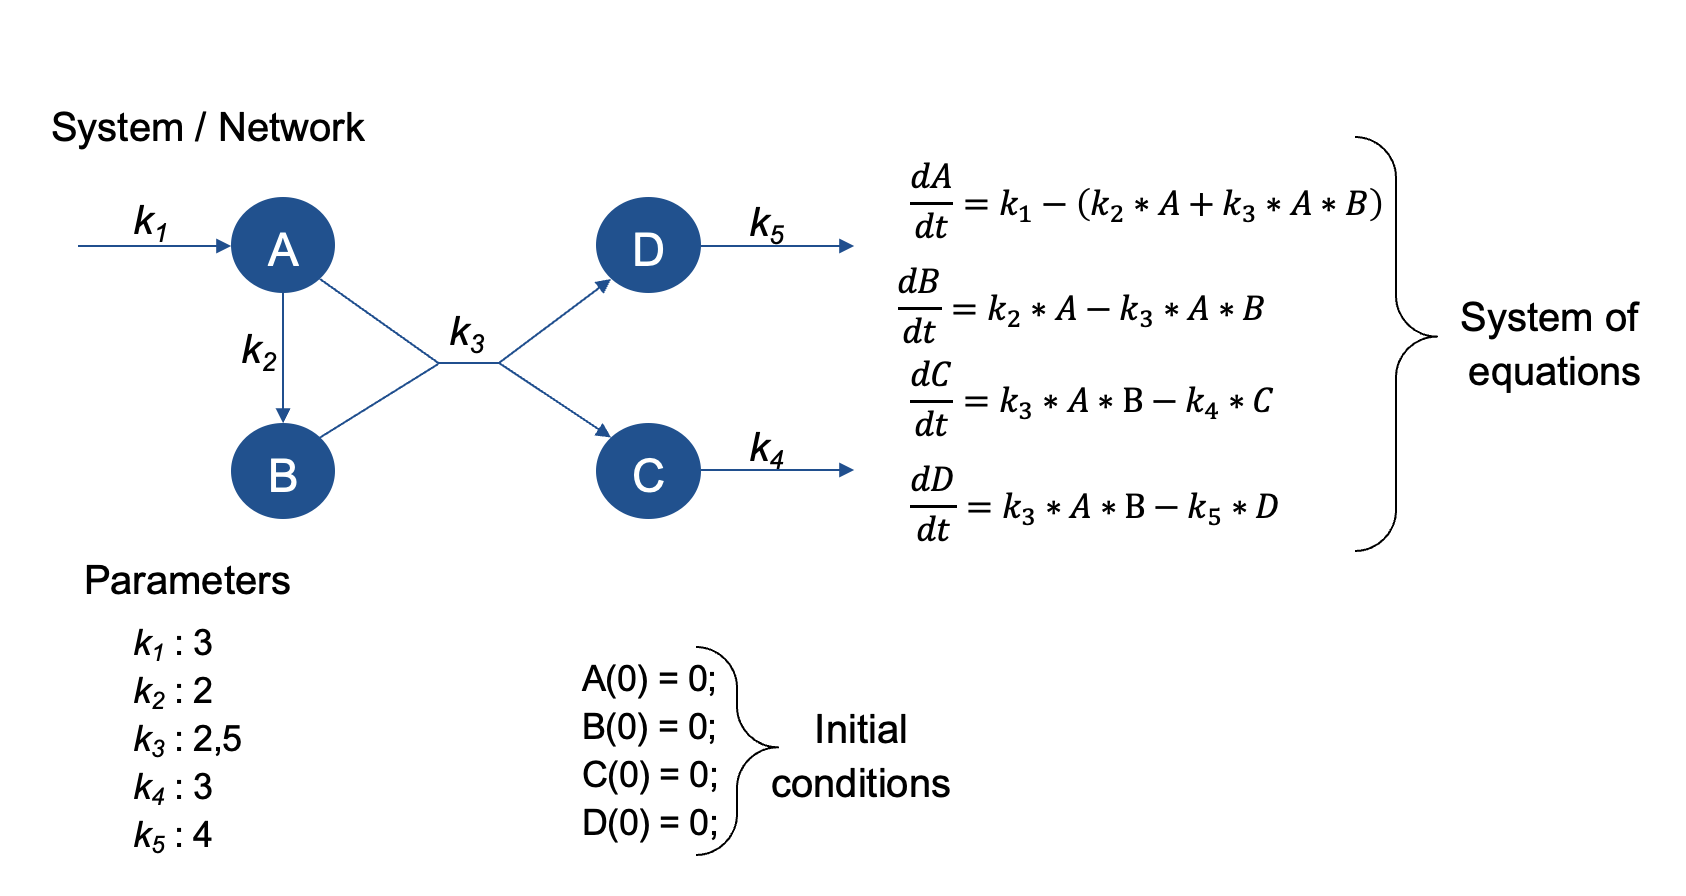

Let's start with setting of initial conditions:

% Let k be wector of reaction rate constants, there k1 = k(1)...k5 = k(5)
k = [3, 2, 2.5, 3, 4];

% Let's collect the concentration values in a compact way using a mathlab structure
state = struct('A',0,'B',0,'C',0,'D',0);

% Let's place the time span to the same structure
dt = 0.01;
state.time = 0:dt:10;


Now let's start with implementation of the differential equesions. We're implementing them as anonimous functions:

dAdt = @(A, B) k(1) - k(2) * A - k(3) * A * B;
dBdt = @(A, B) k(2) * A - k(3) * A * B;
dCdt = @(A, B, C) k(3) * A * B - k(4) * C;
dDdt = @(A, B, D) k(3) * A * B - k(5) * D;


On this step we can define a loop that implements the Euler method for differential equetions:

for i = 1:length(state.time) - 1
    
    % newFunctionValue = oldFunctionValue + derivative * timeStep
    state.A(end+1) = state.A(end) + dAdt(state.A(end), state.B(end)) * dt;
    state.B(end+1) = state.B(end) + dBdt(state.A(end), state.B(end)) * dt;
    state.C(end+1) = state.C(end) + dCdt(state.A(end), state.B(end), state.C(end)) * dt;
    state.D(end+1) = state.D(end) + dDdt(state.A(end), state.B(end), state.D(end)) * dt;

end

After running the system, graphs representing how the variables vary over time can be plotted.

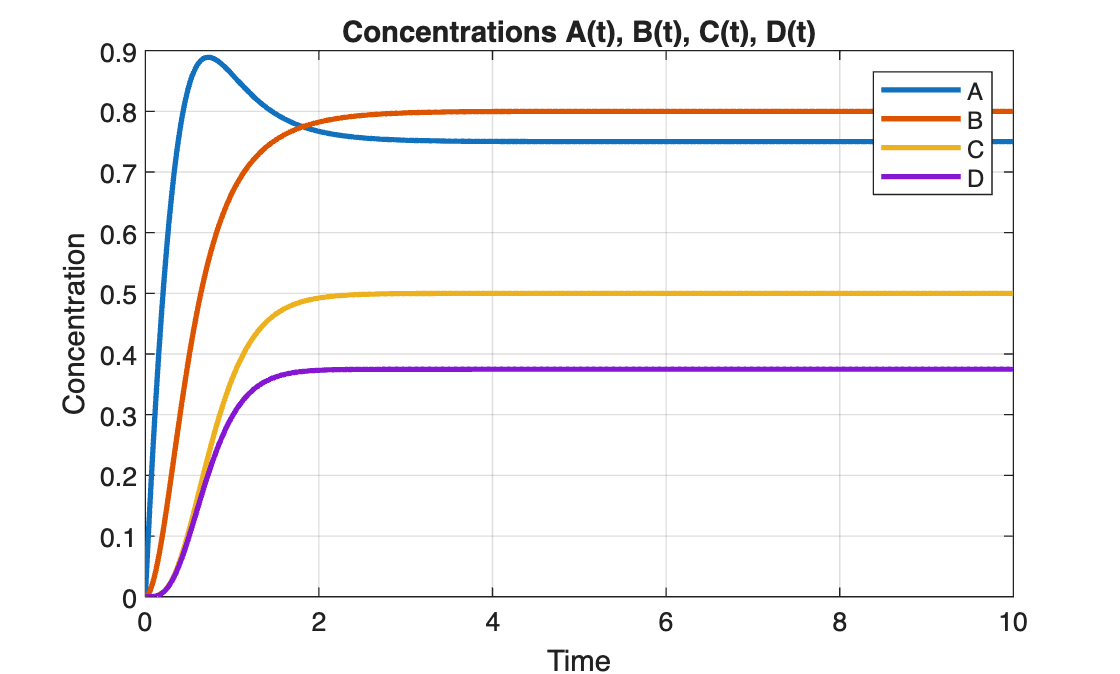

figure;
plot(state.time, state.A, 'LineWidth', 2); hold on;
plot(state.time, state.B, 'LineWidth', 2);
plot(state.time, state.C, 'LineWidth', 2);
plot(state.time, state.D, 'LineWidth', 2);

xlabel('Time');
ylabel('Concentration');
title('Concentrations A(t), B(t), C(t), D(t)');
legend('A','B','C','D');
grid on;
hold off;

Now we focus on molecule B. Using a **for-loop**, we will test several initial values specifically for B and plot the evolution of the system.

For convenience, let’s organise our system of equations as a function — see the implementation at the bottom of the script in the *local functions* section.

And for the sake of time and memory optimisation, let’s store the results in a **vector** instead of a structure this time.  

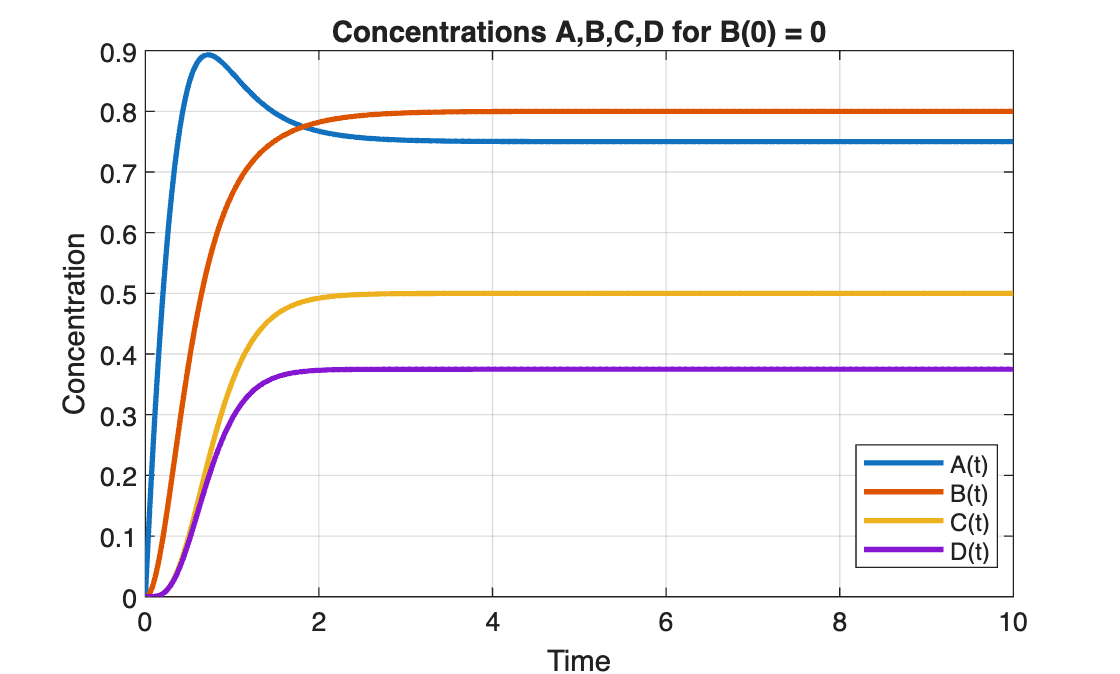

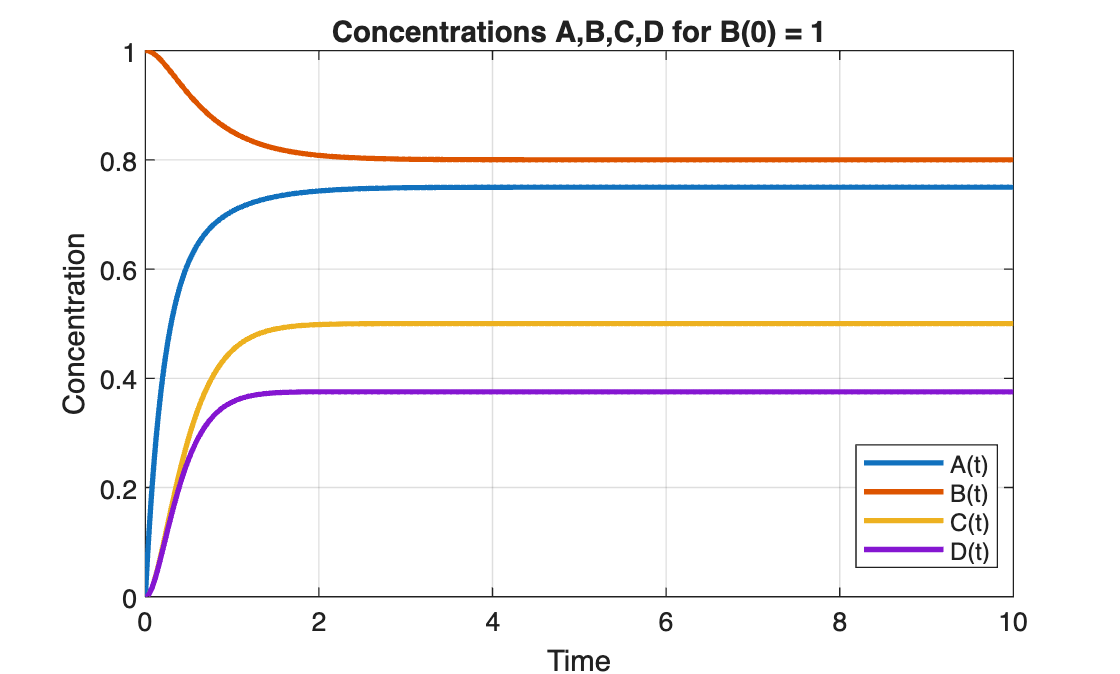

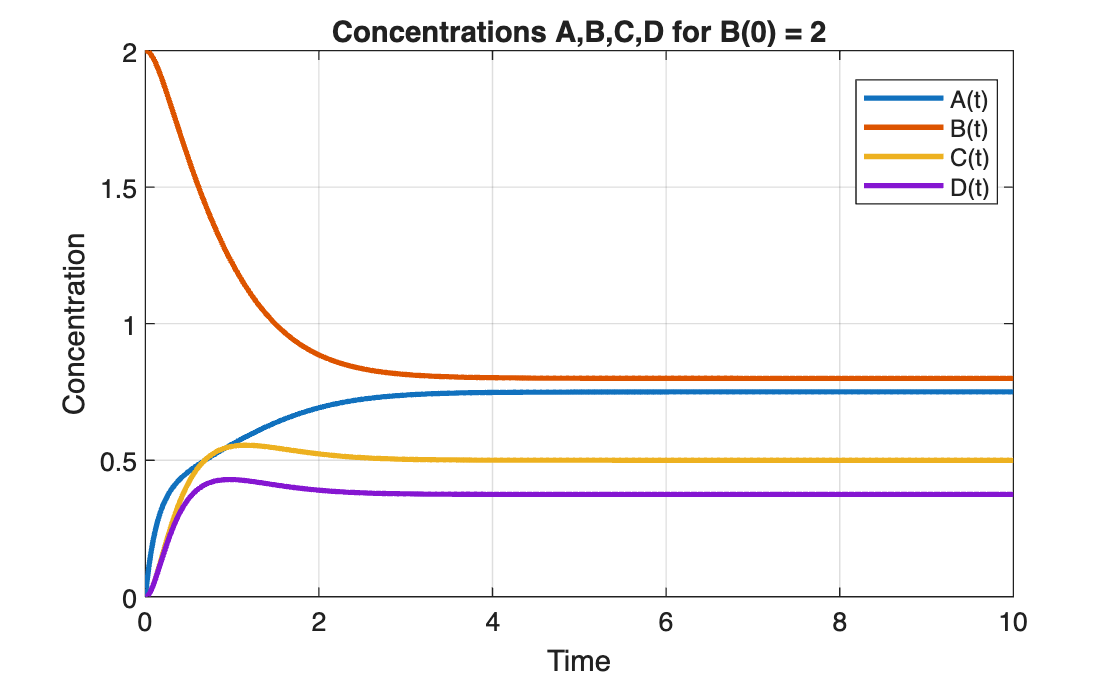

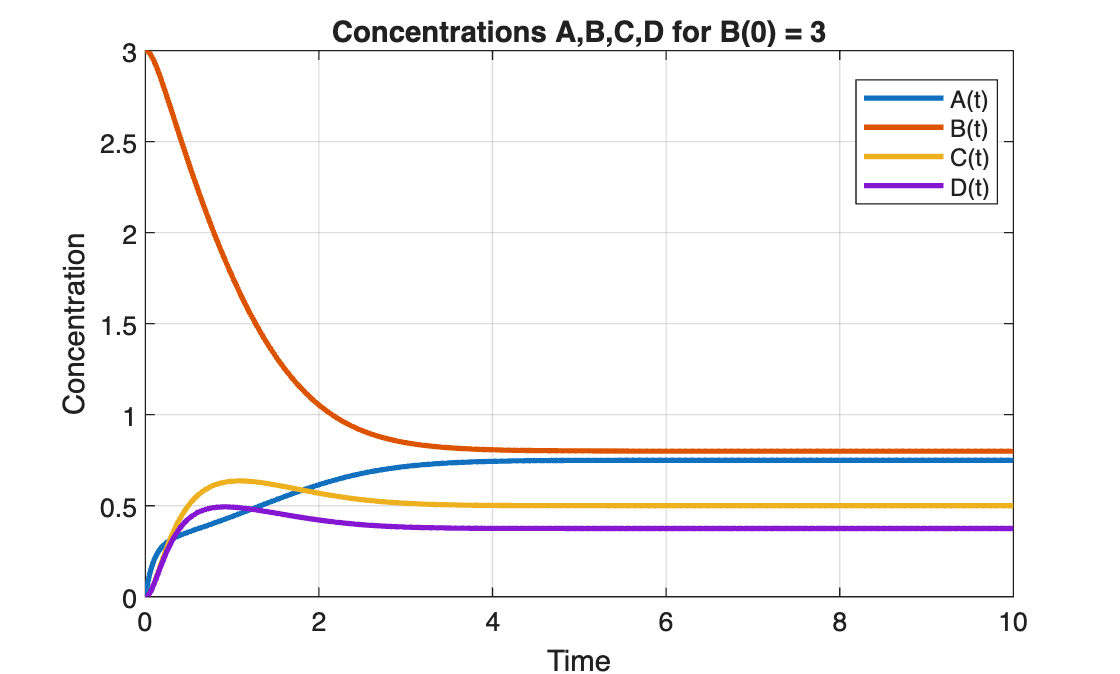

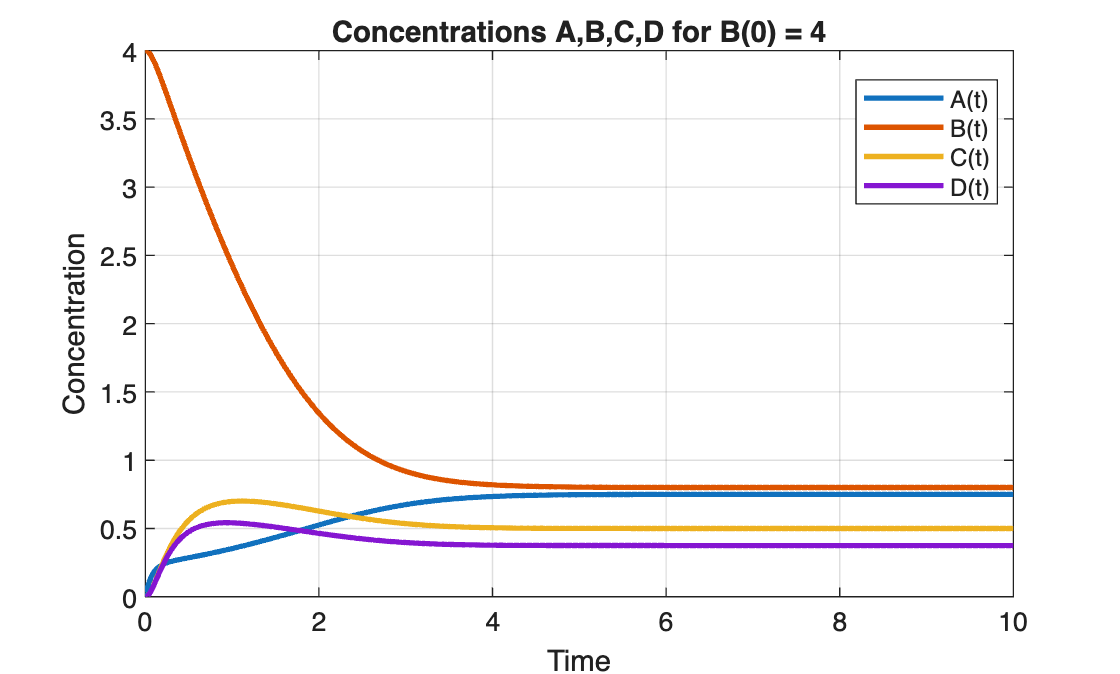

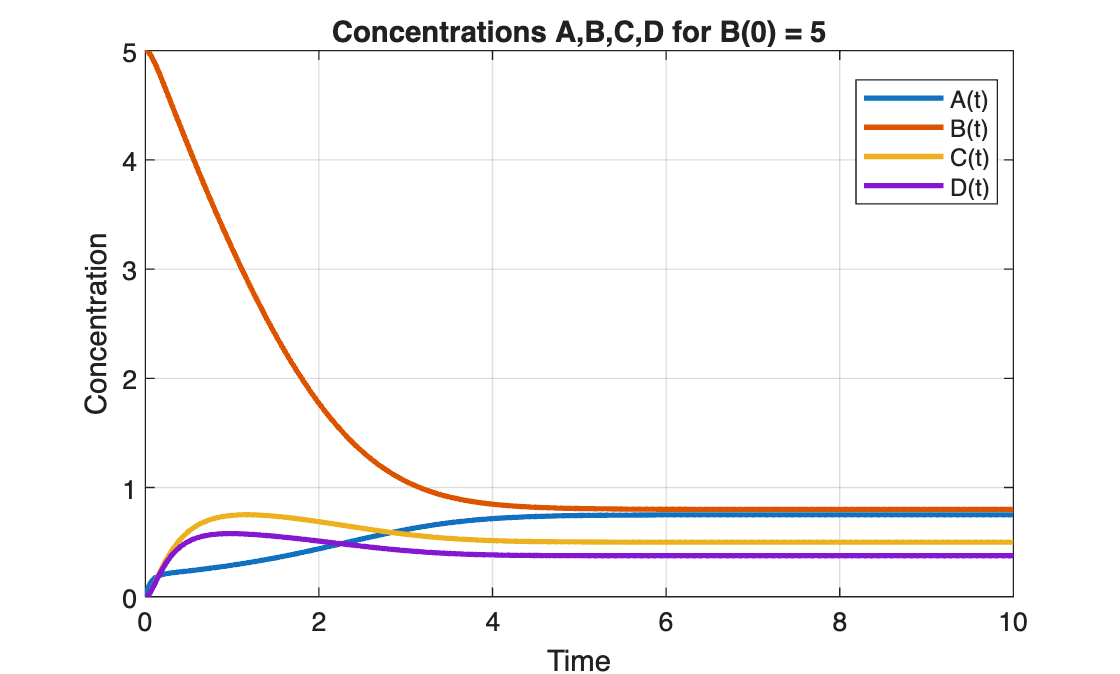

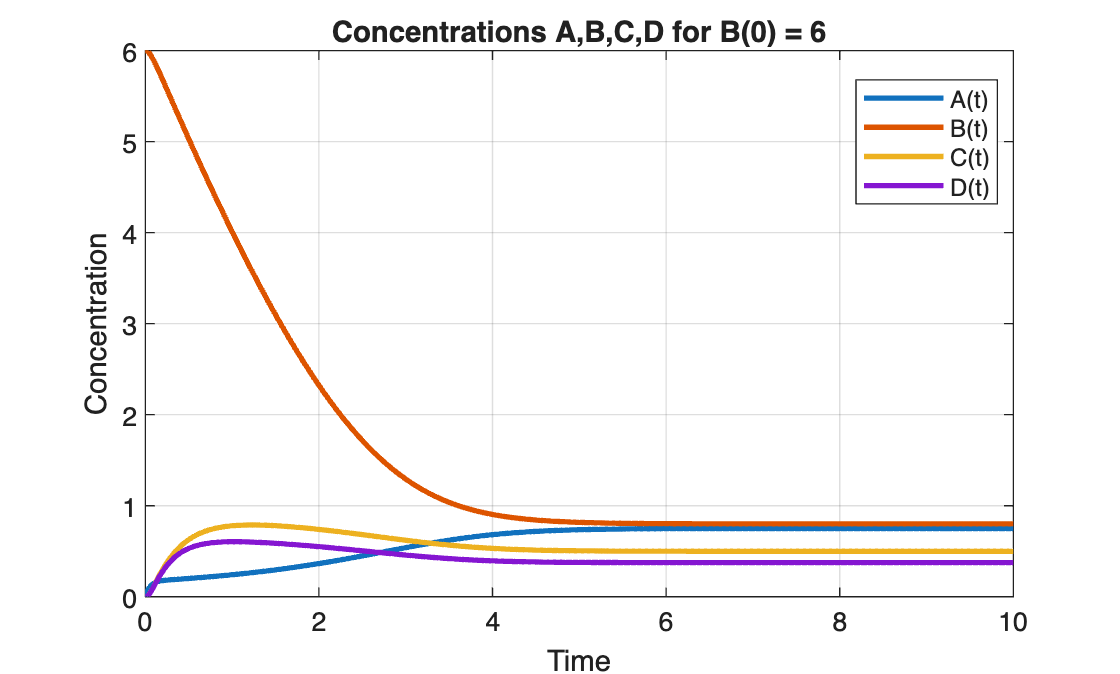

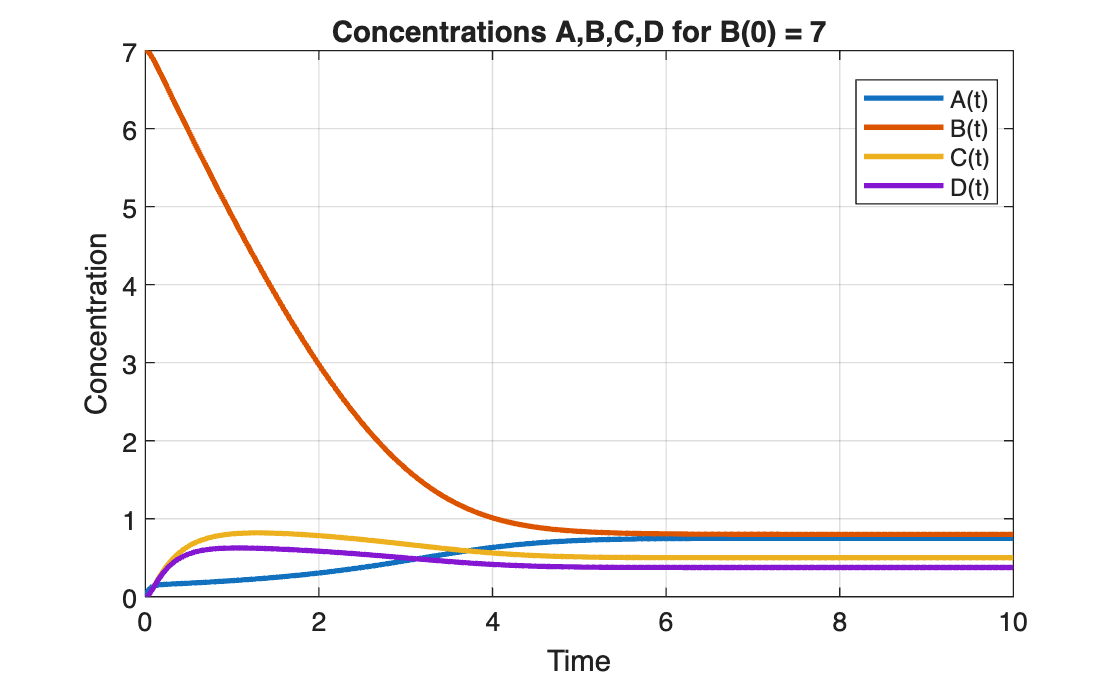

B = 0:1:10; % setting of 10 different values for B
timeSpan = 0:dt:10;

for i = 1:length(B)

    componentsState = zeros(4, length(timeSpan)); % a matrix for setting input values and collecting results
    componentsState(2, 1) = B(i);

    for j = 2:length(timeSpan)
        componentsState(:, j) = eulerMethod(componentsState(:, j-1), k, dt);
    end

    figure;
    
    plot(timeSpan, componentsState(1,:), 'LineWidth', 2); hold on;
    plot(timeSpan, componentsState(2,:), 'LineWidth', 2);
    plot(timeSpan, componentsState(3,:), 'LineWidth', 2);
    plot(timeSpan, componentsState(4,:), 'LineWidth', 2);
    
    title(sprintf('Concentrations A,B,C,D for B(0) = %d', B(i)));
    
    xlabel('Time');
    ylabel('Concentration');
    
    legend('A(t)', 'B(t)', 'C(t)', 'D(t)', 'Location', 'best');
    grid on;
    
    hold off;


end

%% Local functions

function nextState = eulerMethod(currentState, k, dt)

    dAdt = @(A, B) k(1) - k(2) * A - k(3) * A * B;
    dBdt = @(A, B) k(2) * A - k(3) * A * B;
    dCdt = @(A, B, C) k(3) * A * B - k(4) * C;
    dDdt = @(A, B, D) k(3) * A * B - k(5) * D;
        
    nextState = [
        currentState(1) + dAdt(currentState(1), currentState(2)) * dt;
        currentState(2) + dBdt(currentState(1), currentState(2)) * dt;
        currentState(3) + dCdt(currentState(1), currentState(2), currentState(3)) * dt;
        currentState(4) + dDdt(currentState(1), currentState(2), currentState(4)) * dt;
    ];
    
end